# Finite Scale Lyapunov Exponents 

close all 
clear all 

obs_traj = load ('../data/traj_09_03_13_clean.mat');

% delete sections in the Scotia Sea
obs_traj.Yc(obs_traj.Xc>-82) = NaN;
obs_traj.Xc(obs_traj.Xc>-82) = NaN;

%% Models
d=[4, 10];

for i =1:length(d)
    
    [mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));
    
    mod_traj(i).U(mod_traj(i).U==-999) = NaN;
    mod_traj(i).V(mod_traj(i).V==-999) = NaN;
    mod_traj(i).Y(mod_traj(i).X>360-82) = NaN;
    mod_traj(i).U(mod_traj(i).X>360-82) = NaN;
    mod_traj(i).V(mod_traj(i).X>360-82) = NaN;
    mod_traj(i).X(mod_traj(i).X>360-82) = NaN;
    
end

depth = -747.2217

depth = -1.4749e+03


sep_obs = calculate_seperation_timeseries(obs_traj);

% calc sep models
% 
for i = 1
    for j =1:length(d)
        mod_sep(j,i) = model_sep_calcs(mod_traj(j), [0, 50]*1e3); 
    end
end

%  define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));


diff_pres = 100; 
plevel = [500 1000 1800];

flag_1time = 1;
%% 
%[fsle_obs_deep_mean, fsle_obs_deep_ci] = fsle(sep_obs, dist_bin, diff_pres, plevel(2:3), 0, flag_1time); 
[fsle_obs_int_deep_mean, fsle_obs_int_deep_ci] = fsle(sep_obs, dist_bin, diff_pres, plevel(2:3), 1, flag_1time); 

%[fsle_obs_shallow_mean, fsle_obs_shallow_ci] = fsle(sep_obs, dist_bin, diff_pres, plevel(1:2), 0, flag_1time); 
[fsle_obs_int_shallow_mean, fsle_obs_int_shallow_ci] = fsle(sep_obs, dist_bin, diff_pres, plevel(1:2), 1, flag_1time); 


%fsle_mod_deep = fsle_model(mod_sep(2,1).sep, dist_bin, 0, flag_1time); 
fsle_mod_deep_int = fsle_model(mod_sep(2,1).sep, dist_bin, 1, flag_1time); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21




%fsle_mod_shallow = fsle_model(mod_sep(1,1).sep, dist_bin, 0, flag_1time); 
fsle_mod_shallow_int = fsle_model(mod_sep(1,1).sep, dist_bin, 1, flag_1time); 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21



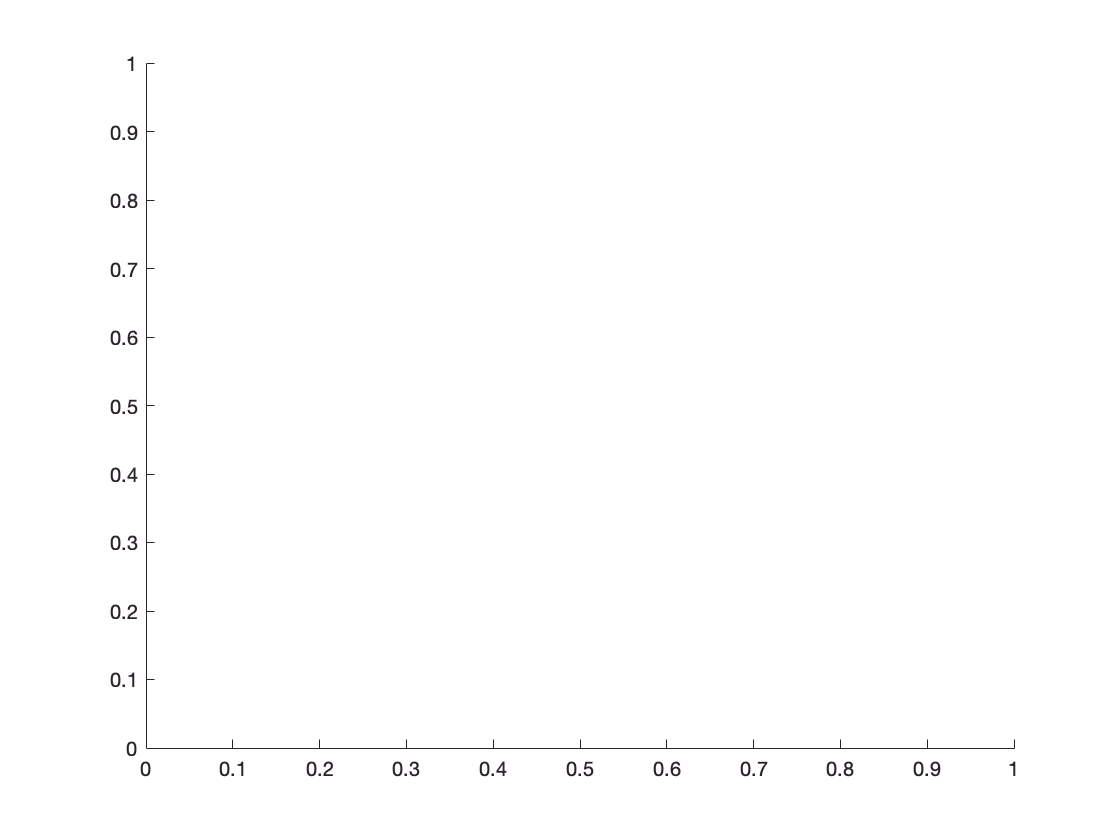

colors = get(gca,'ColorOrder');

col_num = [1,4; 2, 5];

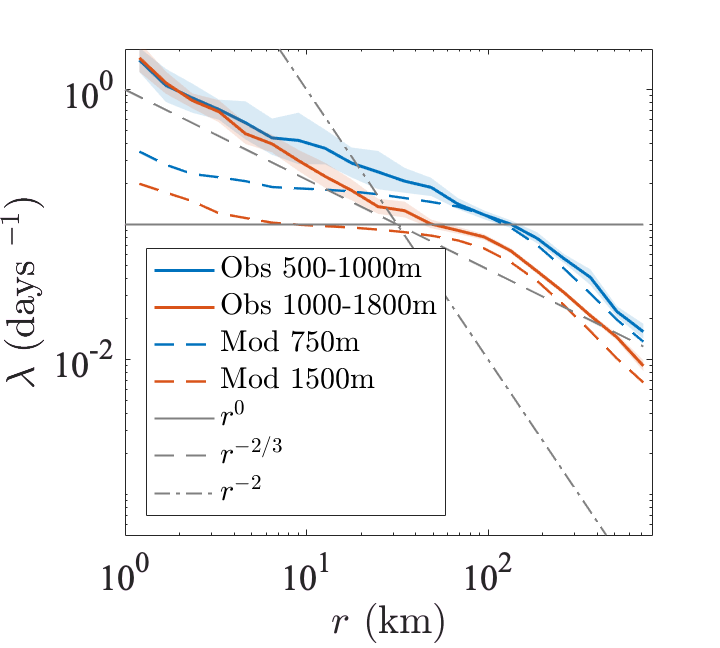

%% Figure for deep
close all 
clear h g 
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','OpenGL')

h(1) = shadedErrorBar_log(dist_axis/1e3, fsle_obs_int_shallow_mean, fsle_obs_int_shallow_ci, ...
            {'-','linewidth',1.5,'color', colors(col_num(1,1),:)}, 1);
hold all        
h(2) = shadedErrorBar_log(dist_axis/1e3, fsle_obs_int_deep_mean, fsle_obs_int_deep_ci, ...
            {'-','linewidth',1.5,'color', colors(col_num(2,1),:)}, 1);

        
%g(1) = loglog(dist_axis/1e3, fsle_mod_deep, '--', 'linewidth',2,'color', colors(2,:));
g(1) = loglog(dist_axis/1e3, fsle_mod_shallow_int, '--', 'linewidth',1.2, 'color', colors(col_num(1,1),:)); 
g(2) = loglog(dist_axis/1e3, fsle_mod_deep_int, '--', 'linewidth',1.2, 'color', colors(col_num(2,1),:)); 

r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 


A = legend([h(1).mainLine, h(2).mainLine, g(1), g(2), r0, r23, r2], ...
    {'Obs 500-1000m', 'Obs 1000-1800m', 'Mod 750m', 'Mod 1500m', '$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',15);
%legend boxoff
%set(A, 'location','best') 
set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 5*1e-4 2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')

print('fsle.eps','-depsc', '-r400')